clear, close all  clc

## Bode-Diagramm einer PT1-Strecke

Aus einer gegebenen Sprungantwort eines PT1-Gliedes (DC-Motor des Motor-Boards von hps-Systemtechnik; Labor) sind die Streckenparameter zu ermitteln und für die Strecke ist ein Bode-Diagramm zu konstruieren.

%<ToDo />
K = 800; %Übertragungsbeiwert in U / min / V
T1 = 55e-3; %Verzögerungszeit in s

## Übertragungsfunktion

Die Übertragungsfunktion G(s) entspricht einer *vollständigen* Beschreibung eines Systems im (komplexen) Frequenzbereich mit der komplexen Frequenz s=sigma+j*w. G(s) stellt eine alternative Beschreibungsform zur Sprungantwort eines Systems dar und ist für die Analyse von regelungstechnischen Fragestellungen oft besser geeignet.

Modellieren sie die PT1-Strecke mit ihrer Übertragungsfunktion.

%<ToDo />
s = tf('s'); %komplexe Frequenz
Gs = K / (1+s*T1); %Übertragungsfunktion

Stellen sie die Sprungantwort und den Frequenzgang der Strecke in einem Fenster dar.

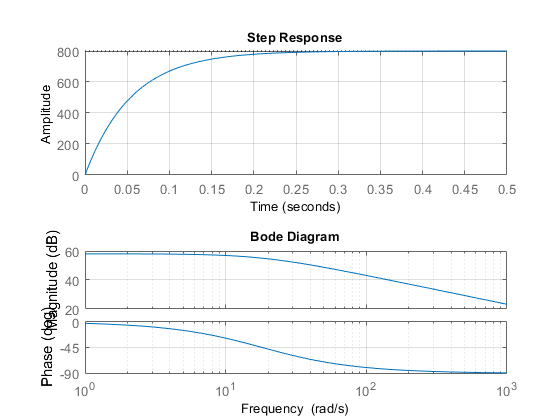

%<ToDo />
figure,
subplot(211), step(Gs), grid on
subplot(212), bode(Gs), grid on

## Frequenzgang (Bode-Diagramm)

Wir in der komplexen Frequenz der Realteil (sigma) Null gesetzt, so erhält man den sogenannten Frequenzgang G(w), der das Systemverhalten für harmonische Anregungen (z.B. Sinus) nach dessen Einschwingen, d.h. für t>5*T1, beschreibt. Bei harmonischer Anregung des Systems schwingen für t>5*T1 sämtliche Größen (Druck, Drehzahl, Spannung, Strom, etc.) mit derselben Anregungs(kreis)frequenz harmonisch und unterscheiden sich ausschließlich durch die Amplitude und die Phasenlage. G(w) ist eine einzige frequenzabhängige komplexe Zahl. Der Betrag abs(G(w))=G=x/y entspricht dabei dem Verhältnis von Ausgangsamplitude x (Regelgröße) zur Eingangsamplitude y (Stellgröße), d.h. der Versätrkung des Systems. Der Winkel (das Argument) arg(G(w))=phi_x-phi_y der komplexen Zahl G(w) entspricht der Phasendrehung zwischen Ein- und Ausgang.

**Logarithmisches Maß - Dezibel (dB)**: Um Berechnungen zu vereinfachen, wird die Verstärkung oft in logarithmierter Form ferwendet, in diesem Fall spricht man von einem Maß GdB = 20*log10(G), welches in Dezibel (dB) angegeben wird. Werden zwei Systeme G1(s) und G2(s) in Reihe geschaltet, so multiplizieren sich deren Versärkungen zur Gesamtverstärkung G=G1*G2. Durch die Verwendung der logarithmischen Maßzahlen wird die "aufwändige" Multiplikation auf eine einfacher durchzuführende Addition zurückgeführt, d.h. GdB = 20*log10(G1*G2) = 20*log10(G1)+20*log10(G2) = G1dB + G2dB!

Stellen sie die Verstärkungen von 1/1000 bis 1000 in Dezibel dar und interpretieren sie das Ergebnis.

%<ToDo />
V = [1/1000, 1/100, 1/10, 1 10, 100, 1000];
VdB = 20*log10(V);

% Anzeige der Tabelle.
disp('     V     |   VdB  ')

     V     |   VdB  


disp('_____________________')

_____________________


disp(num2str([V' VdB'], '%+10.3f | %5.1fdB'))

   +0.001 | -60.0dB
   +0.010 | -40.0dB
   +0.100 | -20.0dB
   +1.000 |   0.0dB
  +10.000 |  20.0dB
 +100.000 |  40.0dB
+1000.000 |  60.0dB


Harmonische (sinusförmige) Eingangssignale werden, abhängig von Ihrer Frequenz w, unterschiedlich vom Streckeneingang zum Streckenausgang hin übertragen.

- **Gleichgröße am Eingang (w=0)**: Bei der Eingangsfrequenz w=0 bzw. s=0 (z.B. konstante Eingangsgröße/Eingangssprung) wird der Nenner des Frequenzgangs G(w)=K/(1+j*w*T1) der PT1-Strecke "1" und die Verstärkung G(0)=K/(1+j*0*T1)=K entspricht dem Übertragungsbeiwert K (rein reell, dh. keine Phasendrehung).

- **Knick-Frequenz (w=w1=1/T1)**: Mit steigender Frequenz w wächst der Imaginärteil w*T1 im Nenner an. Die Frequenz w, bei welcher der Imaginärteil w*T1 gerade gleich groß wie der Realteil "1" wird, nennt man Knickfrequenz w1*T1=1 -> w=w1=1/T1 - ab dieser Frequenz wird der Imaginärteil stetig stärker wirksam. Sind der Real- und Imaginärteil im Nenner beide gleich 1 und damit gerade gleich groß, so wird der Winkel der komplexen Zahl im Nenner arctan(1/1)=45° und der Betrag sqrt(1²+1²)=sqrt(2). Der Frquenzgang (Zähler*Nenner^-1) zeigt daher -45° Phasenverschiebung und eine Verstärkung von K/sqrt(2), d.h. auf etwa 70% abgeschwächt oder um -3dB geschwächt im Vergleich zu Gleichgrößen.

- Für w*T1>>1 überwiegt der Imaginärteil im Nenner und der Bruch wird überwiegend komplex (-90° Phasendrehung).

- Für w*T1<<1 ist G(w) etwa K und ist daher "eher" reell, d.h. hat Phase Null (komplexer Zeiger liegt auf reeller Achse).

Berechnen sie die Verstärkung, das Verstärkungsmaß, die Phasendrehung und den zeitlichen Versatz (w=dphi/dt -> dt=w*dphi) für w=0 und fünf Dekaden der Knickkreisfrequenz, beginnend mit w=w1/100.

%<ToDo />
w1 = 1 / T1; %Knickkreisfreq in 1/s
f1 = w1 / (2*pi); %Knickfreq in Hz
T = 1/f1; %Periodendauer in s

disp('      w    |  |Gw|   | |Gw|[dB] |  phi[°] |  dt[s]   ')

      w    |  |Gw|   | |Gw|[dB] |  phi[°] |  dt[s]   


disp('-----------------------------------------------------')

-----------------------------------------------------



 vW = [1/100, 1/10, 1, 10, 100]*w1;
 
 w = vW(3)

w = 18.1818

 Gw = freqresp(Gs, w) %Komplexe Verstärkung

Gw = 4.0000e+02 - 4.0000e+02i

 
 Gw_magnitude = abs(Gw) %Verstärkung linear

Gw_magnitude = 565.6854

 
 Gw_db = 20 * log10(Gw_magnitude) %Verstärkungsmaß in dB

Gw_db = 55.0515

 phi = rad2deg(angle(Gw)) %Phasendrehung in grad

phi = -45.0000

 dt = angle(Gw) / w %Zeitversatz in s

dt = -0.0432

## Konsturktion des Bode-Diagramms

Ein Bode-Diagramm ist eine stückweise-lineare Näherung des Frequenzganges und kann für eine PT1-Strecke recht "einfach" konstruiert werden. Es müssen nur wenige Größen zur Konstruktion berechnet werden. Konstruieren sie das Bode-Diagramm der gegebenen PT1-Regelstrecke mit Papier und Bleistift.

In guter Näherung kann angenommen werden, dass Eingangsschwingungen mit Frequenzen kleiner oder gleich der Knickfrequenz w1 annähernd mit dem gleichen Verstärkungsmaß verstärkt werden, d.h. gerade so wie konstante Eingangsgrößen mit w=0. Berechnen sie das Verstärkungsmaß für w=0, d.h. G(0)=K.

%<ToDo />


disp( num2str([Gw0 Gw0_dB s_Gw0], '|Gw0|=%.1f  (%.1fdB) entspricht %.1fmm') )

Um das Bode-Diagramm zu konstruieren, muss die Knickkreisfrequenz w1 im Diagramm markiert werden. Die Frequenzachse wird logarithmisch gewählt und in Dekaden untereilt. Die Knickkreisfrequenz wird dazu in wissenschaflticher Darstellung (mit einer Vorkommastelle) in der Form w1=m*10^n angegeben, wobei m der Mantisse im Wertebereich von 1 bis 9.999 und n der Dekade enstpricht. Der Zehner-Logarithmus von w1 ergibt dann log10(w1)=log10(m)+n. Der Wertebereich von log10(m) liegt zwischen 0 und 1 (0 bis 100%) und entspricht dem Streckenanteil von w1 innerhalb der n-ten Dekade.

**Amplitudengang:** Berechnen sie den Zehner-Logarithmus der Mantisse und die Dekade der Knickkreisfrequenz.

%<ToDo />

- Ab der Knickfrequenz w1 fällt die Verstärkung linear mit -20dB pro Dekade ab, d.h eine Verzehnfachung der Frequenz schwächt die Verstärkung auf ein Zehntel ab.

**Phasengang:** Die Konstruktion des Phasengangs ist nur geringfügig schwieriger. 

- Bei der Knickfrequenz w1 hat das System (immer) eine Phasendrehung von -45° (und die Verstärkung hat nur mehr 70% im Vergleich zu Gleichgrößen).

- Eine Dekade unter der Knickfrequenz ist die Änderung des Eingangssignal für die Strecke langsam genug, sodass der Streckenausgang der Eingangsgröße ohne Verzögerung folgen kann, die Phasendrehung ist phi(w)=0° für w<w1/10.

- Eine Dekader über der Knickfrequenz kann der Streckenausgang aufgrund der Streckenträgheit (Verzögerung) dem Eingang nur mehr schlecht folgen. Die Verstärkung ist auf 1/10-tel von K abgefallen (-20dB) und die Phasendrehung ist fast maximal, d.h. 90° (eine Viertelperiode).

- Die Phasendrehung von 0° auf -90° wird durch eine Gerade angenähert, die bei phi(w1/10=0° beginnt und bei phi(10*w1)=-90° ändert. Darunter bzw. darüber ist die Phasendrehung "abgeschlossen" und bleibt konstant.

% Berechnen sie die Frequenz und die Periodendauer der Eingangsschwingung
% bei der Kreisknickfrequenz w1. 


%<ToDo />